image = imread("./Faces/db1_" + 2 + ".jpg");

% Read the image
imIn = image;

% Convert the image to double precision for GrabCut
imIn = im2double(imIn);

% Create a binary mask indicating the initial region (face)
mask = zeros(size(imIn, 1), size(imIn, 2));

% Specify a rectangle that approximately covers the face
rect = [x, y, width, height];  % Define the rectangle coordinates

Unrecognized function or variable 'x'.


% Initialize the GrabCut algorithm
bw = grabcut(imIn, mask, rect);

% Apply the binary mask to the original image
resultImage = bsxfun(@times, imIn, bw) + bsxfun(@times, zeros(size(imIn)), ~bw);

% Display the original image and the result
figure;
subplot(1, 2, 1);
imshow(imIn);
title('Original Image');

subplot(1, 2, 2);
imshow(resultImage);
title('Segmented Face');

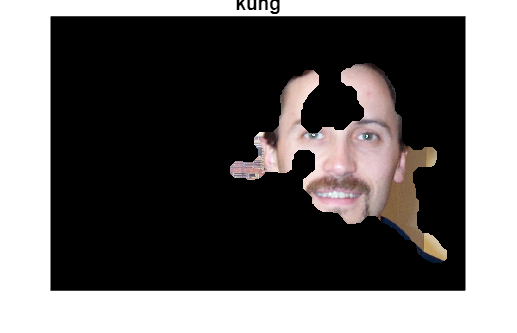

% Read the image
imIn = imread("./Faces/db2/bl_" + 6 + ".jpg");

mask = skinMask(imIn);
imshow(double(mask).*im2double(imIn)); title('kung')